# Load Data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\AnthroFluxesSupPlot'
cd data\input\
%Weather data
load('Bflat30min.mat')
%Pumping volumes and composition
load('BSFPumping.mat');
load('laydownChemistry.mat');
load('laydownvolume.mat');
%Water levels
load('BLM93_AirPresCor.mat')
load('BLM93C.mat')
load('BLM34_complete.mat')
load("BLM31_complete.mat")
load("BLM41_complete.mat")

% cd ..\output\

### Also do one with total volume - right now we have water added to be available for evap, but haven't considered volume increaese.

#### 1. determine the salinity of the brine

laydownChemistry = laydownChemistry(54:66,:);
mean(laydownChemistry.Salinity)

ans = 24.2362

#### 2. determine the % of the volume that was water and not solutes.

laydownvolume.PumpedLaydownVolumeL_withSalinity = laydownvolume.PumpedLaydownVolume_gallons*3.78541;
laydownvolume.PumpedLaydownVolume_m3 = laydownvolume.PumpedLaydownVolume_gallons*0.00378541*(1-mean(laydownChemistry.Salinity)/100); 
%Asumming percent translates into equivalent mass/total. 
%Convert from m2 to km2*m , then divide by 120 for 120 km2
laydownvolume.PumpedLaydownVolume_mm_50km = (laydownvolume.PumpedLaydownVolume_m3/1000000)*1000/50; %equivalent height over the surface
laydownvolume.PumpedLaydownVolume_mm_20km = (laydownvolume.PumpedLaydownVolume_m3/1000000)*1000/20; %equivalent height over the surface
% laydownvolume.PumpedLaydownVolume_mm = laydownvolume.PumpedLaydownVolume_m*1000;

#### Brine is introduced in February and March

bflatAnnualSum = retime(Bflat30min, 'yearly','sum');

BSFPumpingAnnualSum = retime(BSFPumping, "yearly", 'sum');
laydownvolume = retime(laydownvolume, 'yearly','mean');
BSFPumpingAnnualSum = outerjoin(BSFPumpingAnnualSum,laydownvolume);

BLM34 = removevars(BLM34, 'WellID_BLM');
BLM93C = removevars(BLM93C, 'WellID_BLM');
BLM31 = removevars(BLM31, 'WellID_BLM');
BLM41 = removevars(BLM41, 'WellID_BLM');


BLM93C = retime(BLM93C, 'weekly', 'mean');
BLM93 = retime(BLM93, 'weekly', 'mean');
BLM34 = retime(BLM34, 'weekly', 'mean');
BLM34.WaterLevelBelowSurface_m(55:67) = NaN ; %remove bad data
BLM31 = retime(BLM31, 'weekly', 'mean');
BLM41 = retime(BLM41, 'weekly', 'mean');

BflatWeekly = retime(Bflat30min, 'weekly', 'sum');

figure
tiledlayout (4,3)

nexttile ([1,1])
hold on
bar(BSFPumpingAnnualSum.DATE, BSFPumpingAnnualSum.PumpedLaydownVolumeL_withSalinity,1,'DisplayName','brine volum added')
bar(BSFPumpingAnnualSum.DATE, -BSFPumpingAnnualSum.Liters,1, 'DisplayName','brine volume removed')
plot(BSFPumpingAnnualSum.DATE, BSFPumpingAnnualSum.PumpedLaydownVolumeL_withSalinity-BSFPumpingAnnualSum.Liters,...
    "LineWidth",3,'Color', 'black','DisplayName','annual net brine volume')
plot(BSFPumpingAnnualSum.DATE(4:end), cumsum(BSFPumpingAnnualSum.PumpedLaydownVolumeL_withSalinity(4:end) - BSFPumpingAnnualSum.Liters(4:end)),':',...
    "LineWidth",3,'Color', 'black','DisplayName','cumulative net brine volume')
xlim(BSFPumpingAnnualSum.DATE([4,end]))
ylabel 'anthropogenic brine volume (L)'
xlabel('year')
% legend("Location","southoutside")

nexttile ([1,1])
hold on
bar(BSFPumpingAnnualSum.DATE, BSFPumpingAnnualSum.Laydown_TonnesNaCl,1,'DisplayName','solute mass added')
bar(BSFPumpingAnnualSum.DATE, BSFPumpingAnnualSum.Extraction_TonnessNaCl,1, 'DisplayName','solute mass removed')
plot(BSFPumpingAnnualSum.DATE, BSFPumpingAnnualSum.Laydown_TonnesNaCl + BSFPumpingAnnualSum.Extraction_TonnessNaCl,...
    "LineWidth",3,'Color', 'black','DisplayName','annual net solute mass')
plot(BSFPumpingAnnualSum.DATE, cumsum(BSFPumpingAnnualSum.Laydown_TonnesNaCl + BSFPumpingAnnualSum.Extraction_TonnessNaCl) - 3497630,':',...
    "LineWidth",3,'Color', 'black','DisplayName','cumulative net solute mass')


xlim(BSFPumpingAnnualSum.DATE([4,end]))
ylabel 'anthropogenic solute volume (tonnes)'
xlabel('year')
% legend("Location","southoutside")

#### Relative water input

nexttile ([1,1])
hold on
bar(bflatAnnualSum.Date_Time_MDT, bflatAnnualSum.PPT_mm, 1,'FaceAlpha',0.6,'DisplayName','PPT')
bar(laydownvolume.Year, laydownvolume.PumpedLaydownVolume_mm_over20km, 1, 'FaceAlpha',0.6, 'DisplayName','added brine, 20 km area')
bar(laydownvolume.Year, laydownvolume.PumpedLaydownVolume_mm_over50km, 1, 'FaceAlpha',0.6, 'DisplayName','added brine, 50 km area')
xlim([datetime('2016-07-01','InputFormat','yyyy-MM-dd'),datetime('2021-8-01','InputFormat','yyyy-MM-dd')])
% xlim(bflatAnnualSum.Date_Time_MDT([1,end]))
ylabel('water inputs (mm)')
xlabel('year')
% legend("Location","southoutside")

#### Plot water level and PPT over time

nexttile ([1,3])

yyaxis left
hold on 
plot(BLM93.Date_Time_MDT, BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,'color', [0.3010 0.7450 0.9330], 'linewidth', 1.5, 'displayname', '3.5 m well')
plot(BLM93C.Date_Time_MDT, BLM93C.WaterLevelBelowSurface_m*-100,'-', "color",[0 0.4470 0.7410],  'linewidth', 1.5, 'displayname', '0.8 m well')
plot(BLM41.Date_Time_MDT, BLM41.WaterLevelBelowSurface_m*-100,'-.',"color",[0.6350 0.0780 0.1840],  'linewidth', 2, 'displayname', 'BLM-41')
plot(BLM34.Date_Time_MDT, BLM34.WaterLevelBelowSurface_m*-100,'--', "color",[0.7 0.4470 0.7410],  'linewidth', 2, 'displayname', 'BLM-34')
plot(BLM31.Date_Time_MDT, BLM31.WaterLevelBelowSurface_m*-100,':',"color",[0.4660 0.6740 0.1880],  'linewidth', 2, 'displayname', 'BLM-31')

load("BLM34_ThermEff.mat")
load('BLM41_ThermEff.mat')
load('BLM31_ThermEff.mat')
load('BLM93_ThermEff.mat')
load('BLM93C_ThermEff.mat')

ThermEff = 1.065 %BLM93 termal efficiency

ThermEff = 1.0650

BflatWeekly = retime(Bflat30min, 'weekly', 'mean');
BflatWeekly.soilTempScaled = -BflatWeekly.SoilTemp_C*(-ThermEff)/100 + max(BflatWeekly.SoilTemp_C)*(-ThermEff)/100;
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.soilTempScaled*100,'-','color', 'black', 'linewidth', 1, 'displayname', '3.5 m well temp. modeled water depth')

yline(0, 'displayname', '0 evaporation','HandleVisibility','off');
ylim([-80,5])
ylabel('water depth (cm)')

yyaxis right
BflatWeekly = retime(Bflat30min, 'weekly', 'sum');
bar(BflatWeekly.Date_Time_MDT, BflatWeekly.PPT_mm,1,'displayname', 'PPT')
ylabel('PPT (mm)')
ylim([0,50])
% xticklabels([]) 
xlim(BflatWeekly.Date_Time_MDT([66,end]))
% lgnd = legend('location', "northoutside",'fontsize',10);

% set(lgnd,'color','white');

#### Temperature corrected water levels

nexttile ([1,3])
hold on 
plot(BLM93.Date_Time_MDT, BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo*-100,'color', [0.3010 0.7450 0.9330], 'linewidth', 1.5, 'displayname', '3.5 m well')
plot(BLM93C.Date_Time_MDT, BLM93C.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo*-100,'-', "color",[0 0.4470 0.7410],  'linewidth', 1.5, 'displayname', '0.8 m well')
plot(BLM41.Date_Time_MDT, BLM41.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo*-100,'-.',"color",[0.6350 0.0780 0.1840],  'linewidth', 2, 'displayname', 'BLM-41')
plot(BLM34.Date_Time_MDT, BLM34.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo*-100,'--', "color",[0.7 0.4470 0.7410],  'linewidth', 2, 'displayname', 'BLM-34')
plot(BLM31.Date_Time_MDT, BLM31.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo*-100,':',"color",[0.4660 0.6740 0.1880],  'linewidth', 2, 'displayname', 'BLM-31')

yline(0, 'displayname', '0 evaporation','HandleVisibility','off');
ylim([-85,0])
ylabel('modeled water depth without temperature effects (cm)')

xlim(BflatWeekly.Date_Time_MDT([66,end]))

#### Monthly brine removed and added

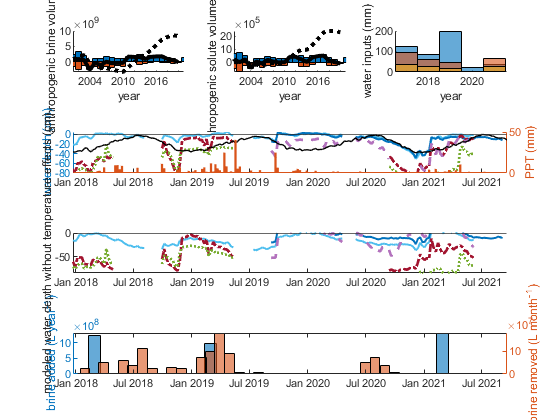

nexttile ([1,3])

laydownvolume.Properties.RowTimes(24) = '01/03/2021';
laydownvolume.Properties.RowTimes(23) = '01/03/2020';
laydownvolume.Properties.RowTimes(22) = '01/03/2019';
laydownvolume.Properties.RowTimes(21) = '01/03/2018';
laydownvolume.Properties.RowTimes(20) = '01/03/2017';

yyaxis right
bar(BSFPumping.DATE, BSFPumping.Liters, 1.1,'EdgeColor','black','FaceAlpha',0.6,'displayname', 'brine removed (L)');
% alpha(s, 0.7)
ylabel('brine removed (L month^-^1)')
ylim([0,1.8*10^8])

yyaxis left
bar(laydownvolume.Year, laydownvolume.PumpedLaydownVolume_gallons*3.78541,0.1, 'FaceAlpha',0.6,'displayname', 'brine added (L)')
ylabel('brine added (L year^-^1)')

xlim(BflatWeekly.Date_Time_MDT([66,end]))
% legend('Location','northoutside')

cd ..\output\
print('AnthropogenicBrineMovement', '-fillpage','-dpdf') %'-bestfit' -fillpage